# Testar Dormand Prince

26/04/2021     Paulo Gouveia        a2020121705.isec.pt

26/04/2021     Miguel Ferreira       a2020107016.isec.pt

26/04/2021     Pablo Amaral         a2020143935.isec.pt

clear
%help function_handle

syms y(t)

f =@(t,y) y+exp(3*t)

f = function_handle with value:
    @(t,y)y+exp(3*t)


%f(0,1)
a = 1

a = 1

b = 1.5

b = 1.5000

n = 20

n = 20

y0 = 2

y0 = 2



yDormandPrince = DormandPrince(f,a,b,n,y0)

yDormandPrince =     2.0000    2.5786    3.2129    3.9076    4.6677    5.4985    6.4058    7.3960    8.4757    9.6522   10.9334   12.3278   13.8446   15.4936   17.2855   19.2317   21.3448   23.6379   26.1257   28.8235   31.7483



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

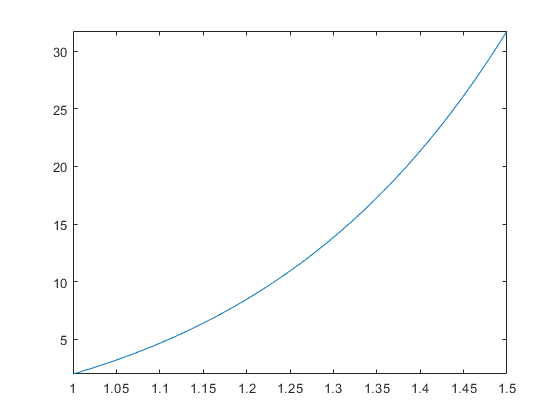

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroDormandPrince = abs(yExata-yDormandPrince);
tabela = [t.',yExata.',yDormandPrince.',erroDormandPrince.']

tabela =     1.0000    2.0000    2.0000    0.0000
    1.0250    2.5786    2.5786    0.0000
    1.0500    3.2129    3.2129    0.0000
    1.0750    3.9076    3.9076    0.0000
    1.1000    4.6677    4.6677    0.0000
    1.1250    5.4985    5.4985    0.0000
    1.1500    6.4058    6.4058    0.0000
    1.1750    7.3960    7.3960    0.0000
    1.2000    8.4757    8.4757    0.0000
    1.2250    9.6522    9.6522    0.0000


array2table(tabela,"VariableNames",{'t','Exata','DormandPrince','erroDormandPrince'})

ans = 21×4 table
      t      Exata     DormandPrince    erroDormandPrince
    _____    ______    _____________    _________________

        1         2            2           1.7764e-15    
    1.025    2.5786       2.5786           6.6223e-12    
     1.05    3.2129       3.2129           1.3944e-11    
    1.075    3.9076       3.9076           2.2054e-11    
      1.1    4.6677       4.6677            3.099e-11    
    1.125    5.4985       5.4985           4.0843e-11    
     1.15    6.4058       6.4058           5.1683e-11    
    1.175     7.396        7.396           6.3581e-11    
      1.2    8.4757       8.4757           7.6657e-11    
    1.225    9.6522       9.6522           9.0971e-11    
     1.25    10.933       10.933           1.0666e-10    
    1.275    12.328       12.328           1.2382e-10    
      1.3    13.845       13.845  

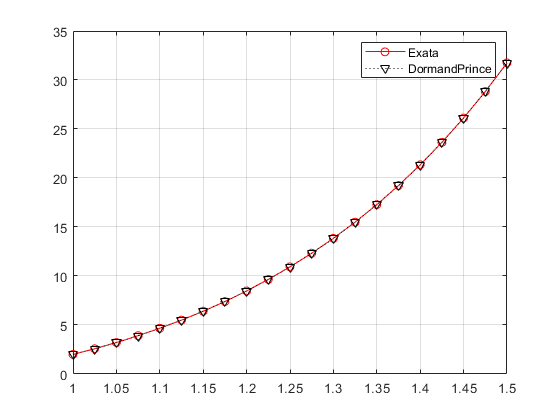


plot(t,yExata,"-ro")
hold on
plot(t,yDormandPrince,"kv:")
hold off
grid on
legend('Exata','DormandPrince')


%whos

 
